# tirファイルからコーナーリングパワーを算出するスクリプト

開始処理

clear; clc;

## ファイル選択と項目設定

tirファイルを選択

filename = "KT_MF_Tool_245_60_R16.tir";

想定する１輪荷重fz[kg]を指定

fz = 400; % kg

## データ取得

タイヤデータを読み込む

if ~matlab.addons.isAddonEnabled("Extended Tire Features for Vehicle Dynamics Blockset")
    error("need to install Extended Tire Features for Vehicle Dynamics Blockset");
end
obj = tireModel.import(filename);

プロットを作成

f1 = figure;
tm1 = plot(obj, Parent=f1, Direction="alpha", Magnitude=1, Fz=fz*9.81);

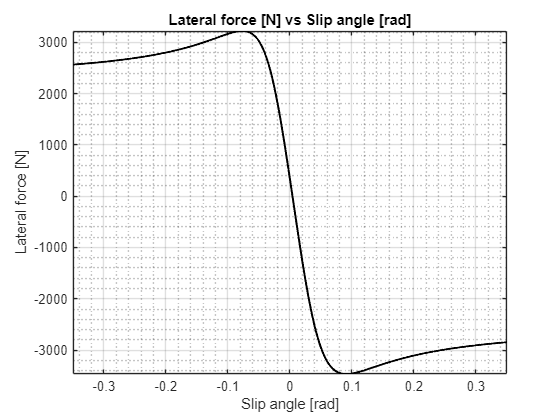

grid on
grid minor
legend off

タイヤデータを取得

set(groot, "ShowHiddenHandles", "on");
h = findobj(f1.Children, "Type", "Axes");
l = findobj(h.Children, "HandleVisibility", "off");
x = l.XData';
y = l.YData';

## スリップ角０°~１°での線形回帰

線形回帰の計算

ind = (abs(x) <= pi/180);
fitobject = fit(x(ind), y(ind), "poly1");
cp = abs(fitobject.p1);
os = fitobject.p2;
disp(['Front tire corner stiffness (N/rad) : ', num2str(cp, '%.0f')])

Front tire corner stiffness (N/rad) : 79085


確認用のグラフプロット

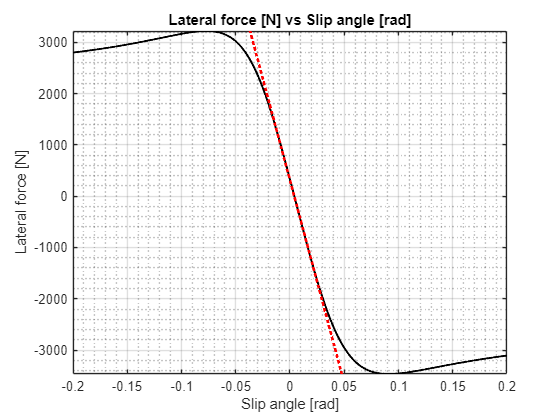

f2 = figure;
tm2 = plot(obj, Parent=f2, Direction="alpha", Magnitude=0.2, Fz=fz*9.81);
xrng = tm2.XLim;
yrng = tm2.YLim;
hold on
plot(x, -cp*x+os, "r:", LineWidth=2);
xlim(xrng);
ylim(yrng);
hold off
grid on
grid minor
legend off

終了処理

set(groot, "ShowHiddenHandles", "off");